Con este codigo se analizara todos los angulos. Creo que tronco no es igual a cadera bro por el momento le puse tronco al angulo de cadera chekea pes luis

clear;
files = dir('angulos_recortados\*.csv');

for k = 1:length(files)
    segmentoR = {};
    segmentoC = {};
    segmentoT = {};
    T = readtable("angulos_recortados\"+files(k).name);

    t = T.Time;
    % Angulo de cadera
    theta1 = calcAngles(...
        T.Angle1_o_0_X,...
        T.Angle1_o_0_Y,...
        T.Angle1_a_0_X,...
        T.Angle1_a_0_Y,...
        T.Angle1_b_0_X,...
        T.Angle1_b_0_Y);
    % Angulo de rodilla
    theta2 = calcAngles(...
        T.Angle2_o_0_X,...
        T.Angle2_o_0_Y,...
        T.Angle2_a_0_X,...
        T.Angle2_a_0_Y,...
        T.Angle2_b_0_X,...
        T.Angle2_b_0_Y);
    
    % Angulo de tronco
    theta3 = calcAnglesT(...
        T.Angle1_o_0_X,...
        T.Angle1_o_0_Y,...
        T.Angle1_b_0_X,...
        T.Angle1_b_0_Y);


    % Correcion de angulo
    theta2 = 180 - theta2;
    theta3 = 180 - theta3;
    
    % Hallar puntos para segmentar
    [~,locs] = findpeaks(theta1,...
    'MinPeakDistance',50,...
    'MinPeakProminence',10);

    % Segmentación
    xC = theta1;
    xR = theta2;
    xT = theta3;
    cortes = [1, locs', length(theta1)];
    for i = 1:length(cortes)-1
        segmentoR{i} = xR(cortes(i):cortes(i+1));
        segmentoC{i} = xC(cortes(i):cortes(i+1));
        segmentoT{i} = xT(cortes(i):cortes(i+1));
    end

    % Guardado de de data
    data(k).archivo = files(k).name;
    data(k).t = t;
    data(k).cadera = theta1;
    data(k).rodilla = theta2;
    data(k).tronco = theta3;
    data(k).segmentosR = segmentoR;
    data(k).segmentosC = segmentoC;
    data(k).segmentosT = segmentoT;
    
    for r = 1:length(data(k).segmentosR)

        thetaR = data(k).segmentosR{r};
    
        [~,locsR] = max(thetaR);
    
        thetaC = data(k).segmentosC{r};
    
        [~,locsC] = min(thetaC);
        
        thetaT = data(k).segmentosT{r};
        [~,locsT] = min(thetaT);
    
        data(k).locsR{r} = locsR;
        data(k).locsC{r} = locsC;
        data(k).locsT{r} = locsT;

        % Verificacion visual
        % figure(Position=[0,0,1200,300])
        % subplot(131)
        % plot(thetaR)
        % hold on
        % plot(locsR, thetaR(locsR), 'ro', 'MarkerFaceColor','r');grid on
        % subplot(132)
        % plot(thetaC)
        % hold on
        % plot(locsC, thetaC(locsC), 'ro', 'MarkerFaceColor','r');
        % subplot(133)
        % plot(thetaT)
        % hold on
        % plot(locsT, thetaT(locsT), 'ro', 'MarkerFaceColor','r');grid on
    
    end

    % Verificacion visual
    %figure;
    %plot(t,theta1); hold on; plot(t(locs),theta1(locs),'ro'); grid on
end

% Separar datos entre pacientes
Participante(1).nombre = "P1";
Participante(1).series = data(1:5);

Participante(2).nombre = "P2";
Participante(2).series = data(6:10);

for p = 1:length(Participante)

    totalRepsT = 0;
    totalRepsR = 0;

    for r = 1:length(Participante(p).series)

        thetaR = Participante(p).series(r).rodilla;
        [~,locsR] = findpeaks(thetaR,...
            'MinPeakProminence',8,...
            'MinPeakDistance',100);

        thetaC = Participante(p).series(r).tronco;
        [~,locsT] = findpeaks(-thetaC,...
            'MinPeakProminence',20,...
            'MinPeakDistance',100);

        totalRepsT = totalRepsT + length(locsT);
        totalRepsR = totalRepsR + length(locsR);

        % figure(Position=[0,0,1200,300])
        % subplot(121)
        % plot(thetaR)
        % hold on
        % plot(locsR, thetaR(locsR), 'ro', 'MarkerFaceColor','r');grid on
        % subplot(122)
        % plot(thetaT)
        % hold on
        % plot(locsT, thetaT(locsT), 'ro', 'MarkerFaceColor','r');grid on

    end
    fprintf("Participante %d\n",p)
    fprintf('Total de repeticiones de tronco: %d\n',totalRepsT)
    fprintf('Total de repeticiones de rodilla: %d\n',totalRepsR)
    fprintf("Total: %d\n",(totalRepsR+totalRepsT)/2)

end

Participante 1


Total de repeticiones de tronco: 17


Total de repeticiones de rodilla: 17


Total: 17


Participante 2


Total de repeticiones de tronco: 18


Total de repeticiones de rodilla: 18


Total: 18


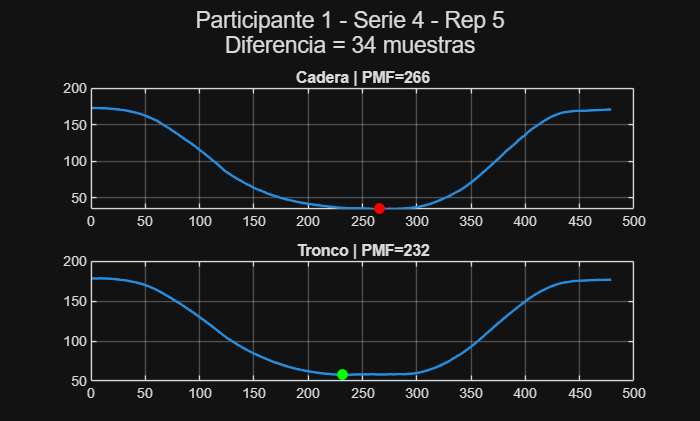

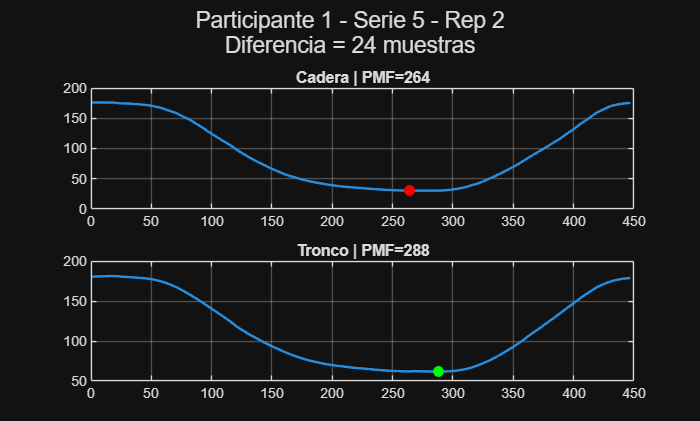

Participante(1).seriesAnalizar = 3:5;
Participante(2).seriesAnalizar = 3:5;
% for p = 1:length(Participante)
% 
%     seriesAnalizar = Participante(p).seriesAnalizar;
% 
%     for s = seriesAnalizar
% 
%         serie = Participante(p).series(s);
% 
%         for r = 1:length(serie.segmentosC)
% 
%             rep = struct();
% 
%             thetaC = serie.segmentosC{r};
%             thetaR = serie.segmentosR{r};
%             thetaT = serie.segmentosT{r};
% 
%             tRep = serie.segmentosTiempo{r};
% 
%             idxPI  = 1;
%             idxPMF = serie.locsC{r};
%             idxPF  = length(thetaC);
% 
%             rep.numRep = r;
% 
%             rep.thetaC_PI  = thetaC(idxPI);
%             rep.thetaC_PMF = thetaC(idxPMF);
%             rep.thetaC_PF  = thetaC(idxPF);
% 
%             idxPMF = serie.locsR{r};
%             rep.thetaR_PI  = thetaR(idxPI);
%             rep.thetaR_PMF = thetaR(idxPMF);
%             rep.thetaR_PF  = thetaR(idxPF);
% 
%             idxPMF = serie.locsT{r};
%             rep.thetaT_PI  = thetaT(idxPI);
%             rep.thetaT_PMF = thetaT(idxPMF);
%             rep.thetaT_PF  = thetaT(idxPF);
% 
%             rep.ROM_C = calcROM(thetaC);
%             rep.ROM_R = calcROM(thetaR);
%             rep.ROM_T = calcROM(thetaT);
% 
%             [rep.texc, rep.tcon] = calcPhases(tRep,idxPMF);
%             rep.ttot = calcDuration(tRep);
% 
%             Participante(p).series(s).rep(r) = rep;
% 
%         end
%     end
% end

umbral = 10; % muestras

for p = 1:length(Participante)

    for s = Participante(p).seriesAnalizar

        serie = Participante(p).series(s);

        for r = 1:length(serie.locsC)

            locsC = serie.locsC{r};
            locsT = serie.locsT{r};

            diferencia = abs(locsC-locsT);

            if diferencia > umbral

                thetaC = serie.segmentosC{r};
                thetaT = serie.segmentosT{r};

                figure('Name',...
                    sprintf('P%d-S%d-R%d',p,s,r))

                subplot(211)
                plot(thetaC,'LineWidth',1.5)
                hold on
                plot(locsC,thetaC(locsC),...
                    'ro','MarkerFaceColor','r')
                title(sprintf(...
                    'Cadera | PMF=%d',locsC))
                grid on

                subplot(212)
                plot(thetaT,'LineWidth',1.5)
                hold on
                plot(locsT,thetaT(locsT),...
                    'go','MarkerFaceColor','g')
                title(sprintf(...
                    'Tronco | PMF=%d',locsT))
                grid on

                sgtitle(sprintf(...
                    'Participante %d - Serie %d - Rep %d\nDiferencia = %d muestras',...
                    p,s,r,diferencia))

            end

        end

    end

end

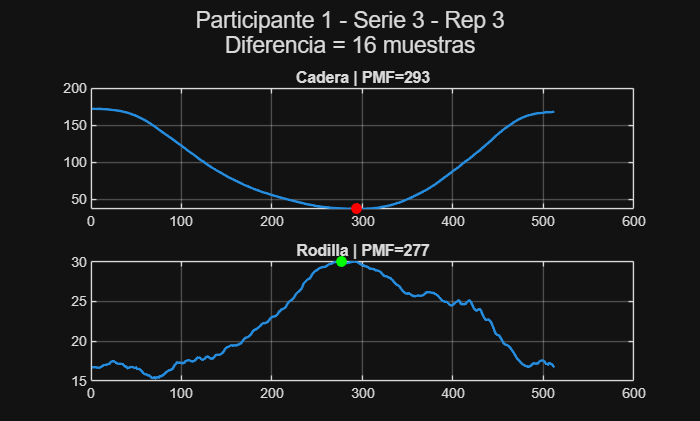

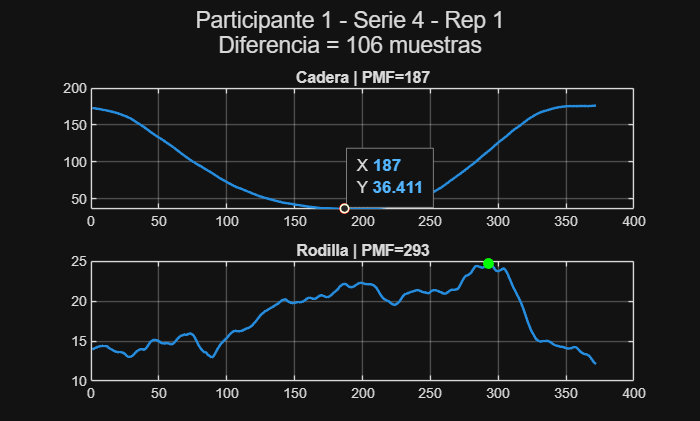

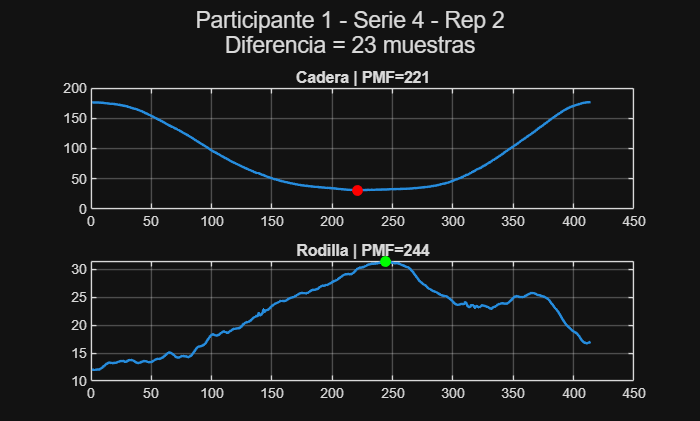

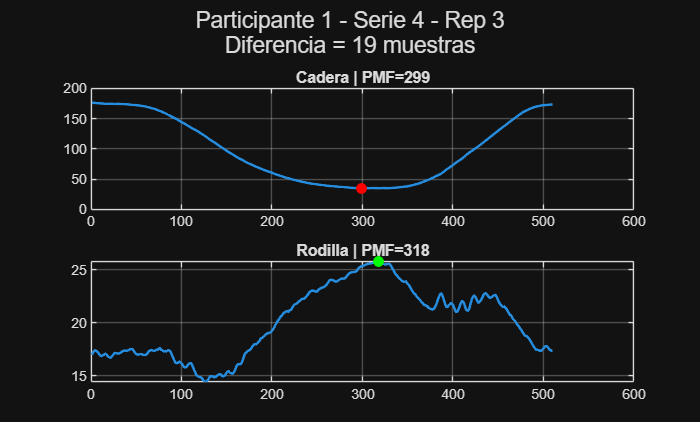

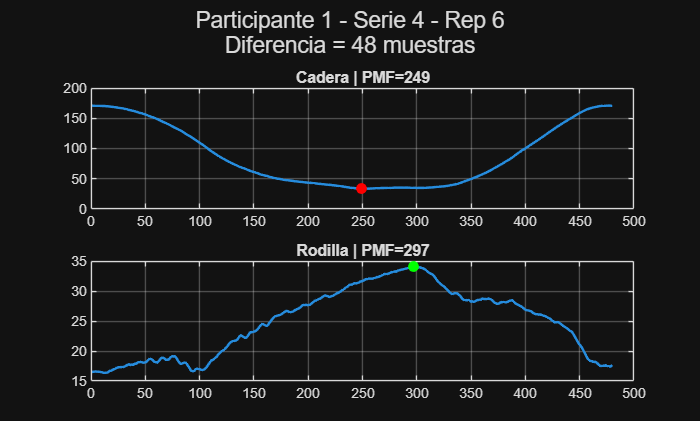

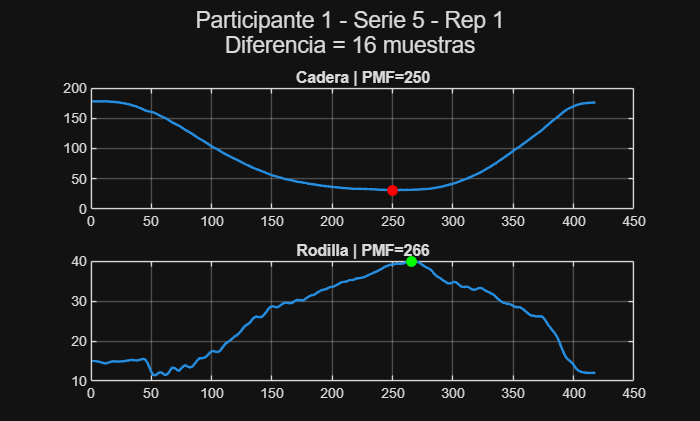

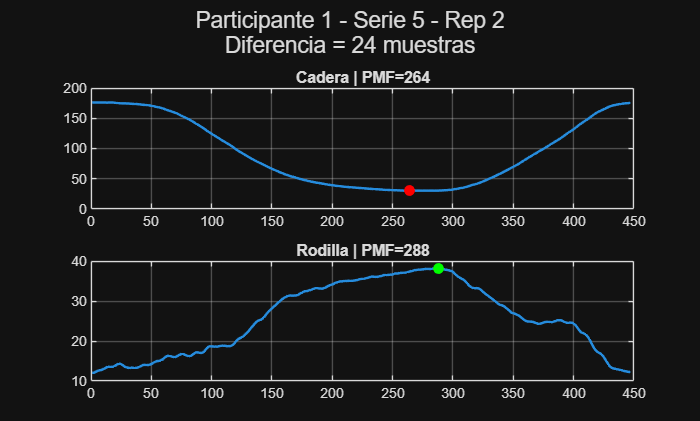

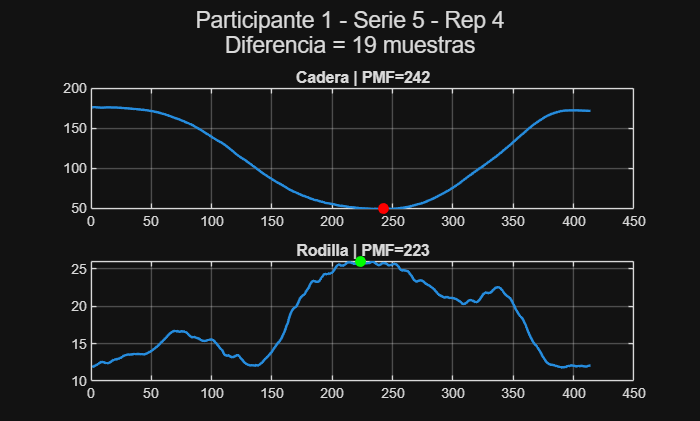

for p = 1:length(Participante)

    for s = Participante(p).seriesAnalizar

        serie = Participante(p).series(s);

        for r = 1:length(serie.locsC)

            locsC = serie.locsC{r};
            locsR = serie.locsR{r};

            diferencia = abs(locsC-locsR);

            if diferencia > umbral

                thetaC = serie.segmentosC{r};
                thetaR = serie.segmentosR{r};

                figure('Name',...
                    sprintf('P%d-S%d-R%d',p,s,r))

                subplot(211)
                plot(thetaC,'LineWidth',1.5)
                hold on
                plot(locsC,thetaC(locsC),...
                    'ro','MarkerFaceColor','r')
                title(sprintf(...
                    'Cadera | PMF=%d',locsC))
                grid on

                subplot(212)
                plot(thetaR,'LineWidth',1.5)
                hold on
                plot(locsR,thetaR(locsR),...
                    'go','MarkerFaceColor','g')
                title(sprintf(...
                    'Rodilla | PMF=%d',locsR))
                grid on

                sgtitle(sprintf(...
                    'Participante %d - Serie %d - Rep %d\nDiferencia = %d muestras',...
                    p,s,r,diferencia))

            end

        end

    end

end















% Funciones
function theta = calcAngles(Ox, Oy, Ax, Ay, Bx, By)

    OAx = Ax - Ox;
    OAy = Ay - Oy;

    OBx = Bx - Ox;
    OBy = By - Oy;

    dotprod = OAx.*OBx + OAy.*OBy;
    crossprod = OAx.*OBy - OAy.*OBx;

    theta = atan2d(crossprod, dotprod);

    theta(theta < 0) = theta(theta < 0) + 360;

end
function theta = calcAnglesT(Ox, Oy, Ax, Ay)

    OAx = Ax - Ox;
    OAy = Ay - Oy;
    
    theta = atan2d(OAx, OAy);
end
% Funciones para calcular variables individuales
function rom = calcROM(theta)

    rom = max(theta) - min(theta);

end
function dur = calcDuration(t)

    dur = t(end) - t(1);

end
function velMax = calcMaxAngularVelocity(theta,t)

    omega = gradient(theta,t);

    velMax = max(abs(omega));

end
% idxMax son los locs de rodilla o tronco
function [tEcc,tCon] = calcPhases(t,idxMax) 

    tEcc = t(idxMax) - t(1);

    tCon = t(end) - t(idxMax);

end
